clear;
global Fs lengthOf1 m c_m;
Fs = 48000; % Samplerate
lengthOf1 = 0.8; % Dauer einer "ganzen Note" in Sekunden
m = [1 2 3 4 6 8 10 12 14 16 18 20 24]; % Vektor der implementierten Obertöne
c_m = [0 0.7092 0 1 0.2530 0.1794 0.0903 0 0 0 0.1 0.05 0.1];
mainVolume = 0.01;

y = makeTone(44, 1, 0.1); % gespielter Ton

Y = fft(y);
Yi = [Y(1:end/2) zeros(1, length(Y)+1) Y(end/2+1:end)]; % durch Nullen Länge verdoppeln

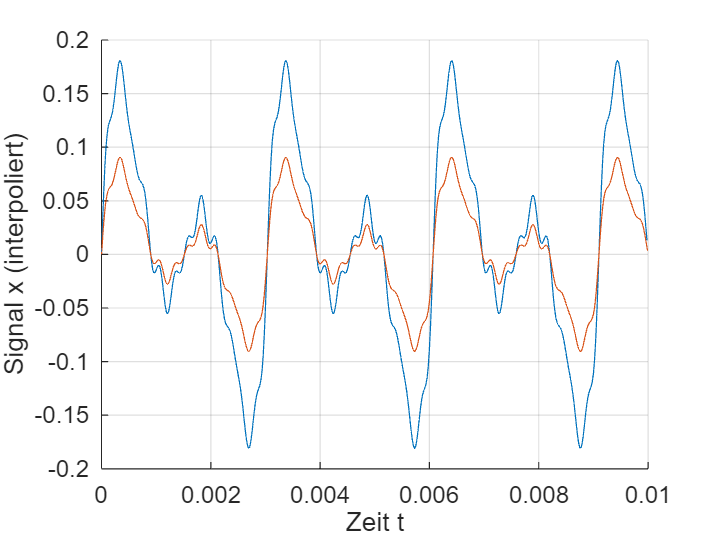


x = ifft(Y);
xi = ifft(Yi);

sound(x,48000);

pause(4);

sound(real(xi), 96000);

t1 = 0: 1/(48000 - 1) :0.01;
t2 = 0: 1/(96000 - 1) :0.01;

hold on;
plot(t1, real(x(1, 1:length(t1))));
xlabel("Zeit t");
ylabel("Signal x (original)");
grid on;
plot(t2, real(xi(1, 1:length(t2))));
xlabel("Zeit t");
ylabel("Signal x (interpoliert)");
grid on;
hold off;

Durch die Berechnungen verzögert sich die Ausgabe, was bei Live-Musik nicht erwünscht ist. Zudem ist keine Steigerung der Qualität hörbar. Zwar wird durch die Interpolation die Charakteristik des Instruments spürbarer, aber für einen merkbaren Effekt reicht eine Verdopplung nicht aus.